## Sound reflection in 1D as a function of R

Showing the sound field in front of a boundary in 1D: incident + reflection sound field

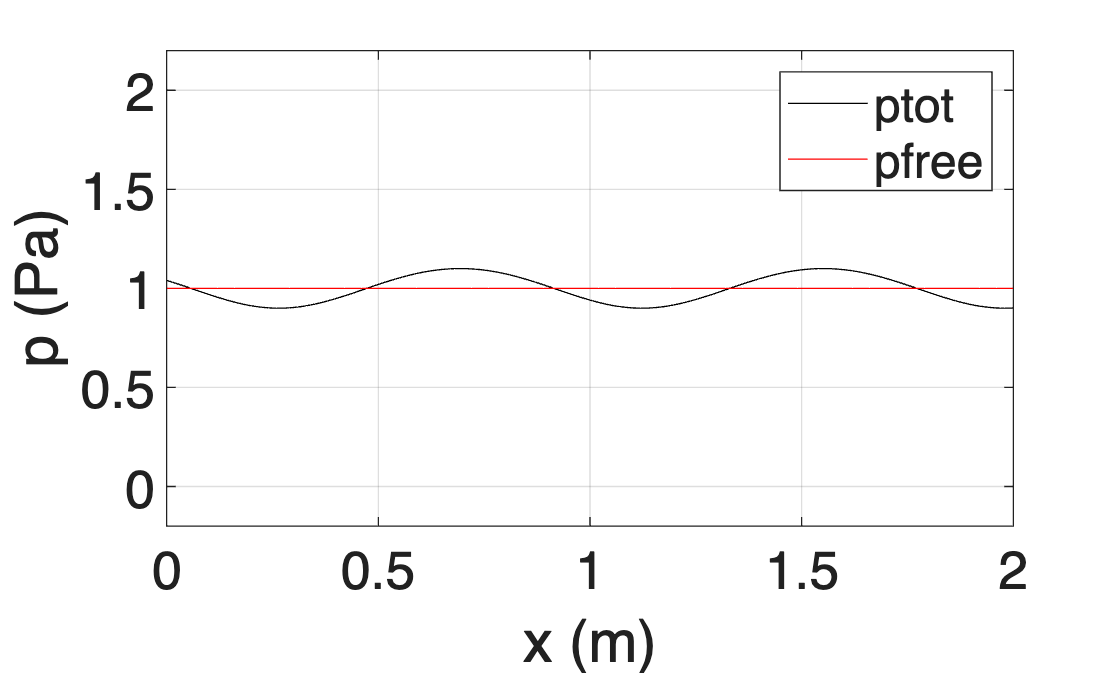

f       =   200;       %   frequency (Hz)
x       =   2;          %   length of 1D domain (m)
c       =   343;        %   speed of sound (m/s)
Ramp    =   0.1;   %  amplitude of reflection coefficient 
Rphase  =   1.2 ;  %  phase of reflection coefficient

oneDreflection(Ramp,Rphase,f,x,c);

## Sound reflection in 1D as a function of Z

Showing the sound field in front of a boundary in 1D: incident + reflection sound field

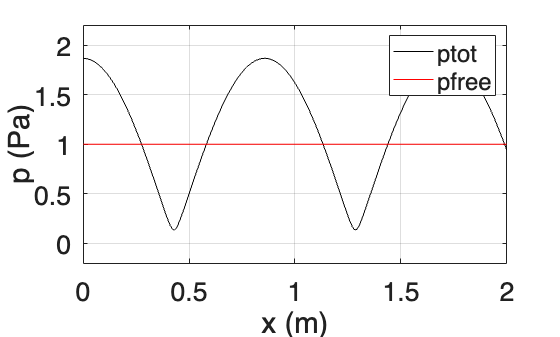

f       =   200;       %   frequency (Hz)
x       =   2;          %   length of 1D domain (m)
c       =   343;        %   speed of sound (m/s)
Zamp    =   14;   %  amplitude of normalized impedance
Zphase  =   0.03 ;  %  phase of normalized impedance

oneDreflectionZ(Zamp,Zphase,f,x,c);

## Reflection coefficient

Showing the reflection coefficient as a function of the angle of incidence

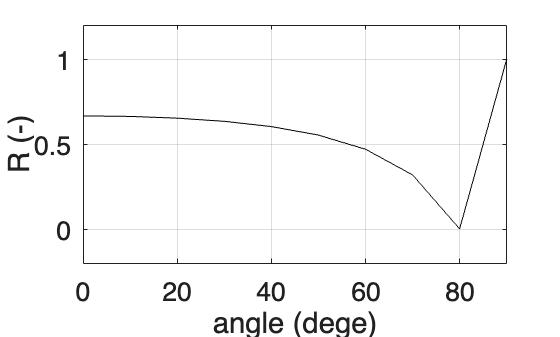

f       =   100;       %   frequency (Hz)
c       =   343;        %   speed of sound (m/s)
c2      =   0.5;       % ratio of sound speed in boundary material relative to speed of sound in air
Zamp    =   5;   %  amplitude of normalized impedance

Rangle(Zamp,f,c,c2)

## Porous material

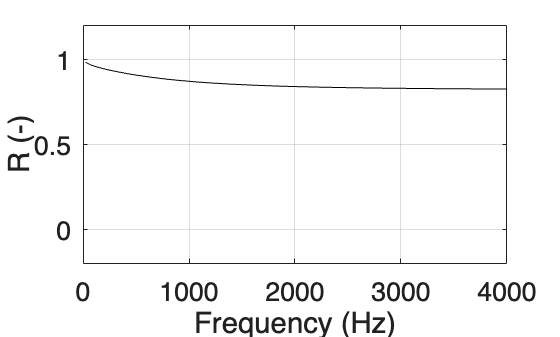

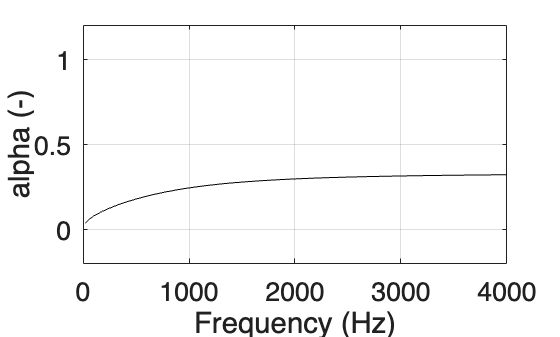

fmax = 4000;
fres = 100000;     % flow resistivity (Pa.s/m^2)
poro = 0.1;       % porosity (-)

Rflowresistivity(fres,poro,fmax)

## Porous material with hard backing

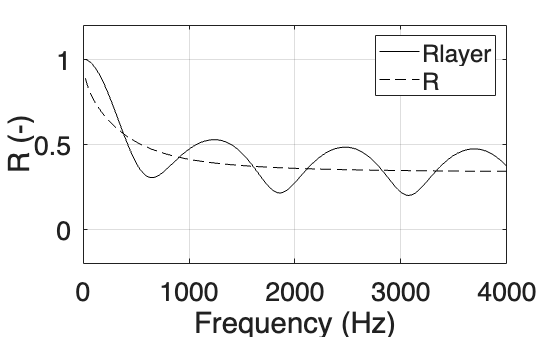

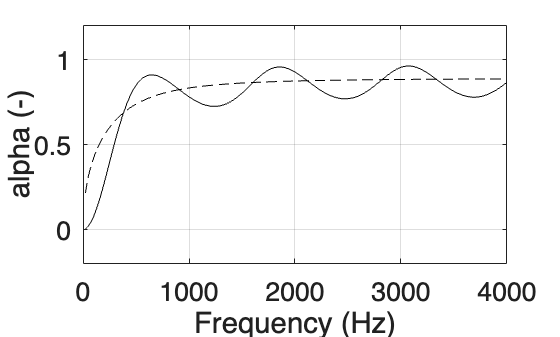

fmax = 4000;
fres = 11000;     % flow resistivity (Pa.s/m^2)
poro = 0.5;       % porosity (-)
d = 0.07;          % thickness (m)

Rporousbacking(fres,poro,fmax,d)

## Porous sheet with hard backing

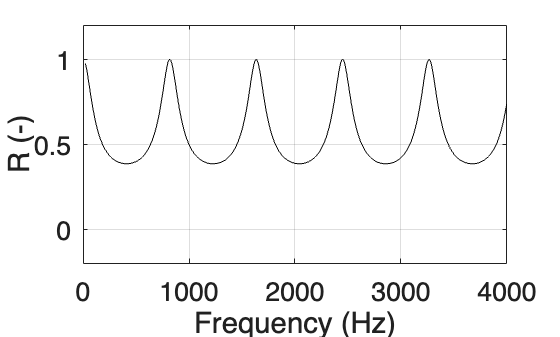

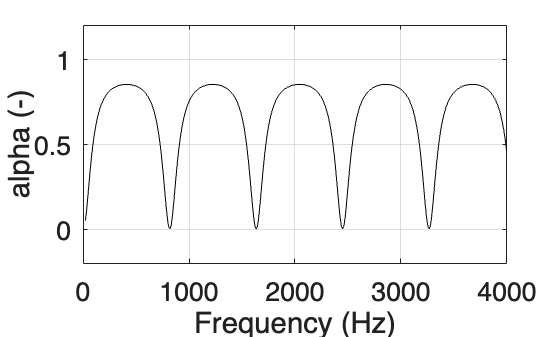

fmax = 4000;
r = 2.25;  % resistance of sheet, which will be multiplied by the impedance of air
d = 0.21;  % cavity width (m)

Rsheet(r,fmax,d)

## Sheet with hard backing

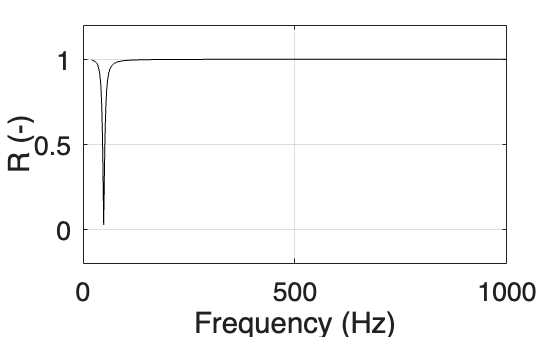

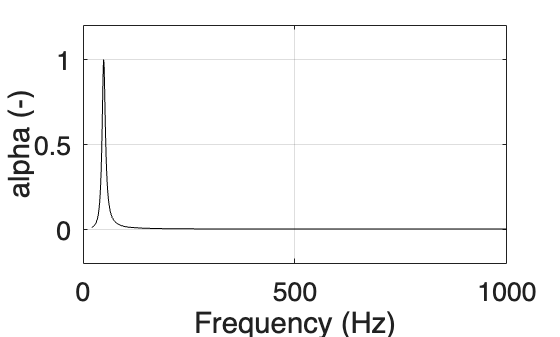

fmax = 1000;
mp = 14;  % mass of the sheet (kg/m^2)
d = 0.11;  % cavity width (m)

Rpanel(mp,fmax,d)

## Perforated plate on porous material with hard backing

mp = 0.0800

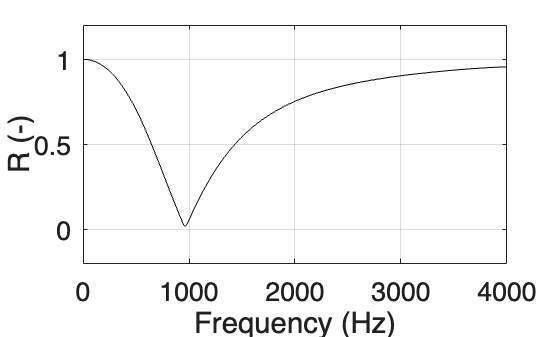

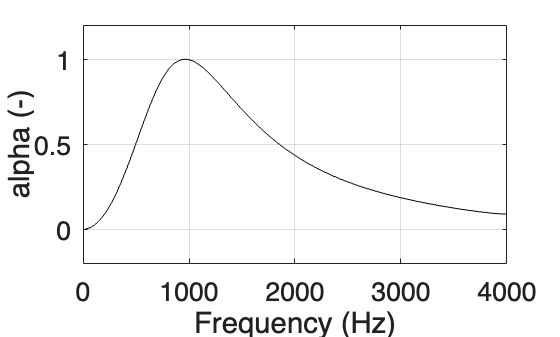

fmax = 4000;                                    % maximum frequency of interest (Hz)
pt = 10;                  % perforated panel thickness (mm)
fres = 1000;            % flow resistivity porous material (kg.s/m^2)
poro = 1;              % porosity of porous material (-)
d = 0.04;                 % thickness of porous material (m)
radius = 0.005;                                 % radius of perforation holes (m)
pr = 0.3;                                       % fraction of plate that is perforated (-)

Rporouspanel(fres,poro,pt,fmax,d,radius,pr)

### Help functions

Feel free to modify to make it better!

function oneDreflection(Ramp,Rphase,f,x,c)
close all
xv = 0:0.01:x;
k = 2*pi*f./c;
R = Ramp.*exp(j*Rphase);
ptot = exp(-j.*k.*xv)+R.*exp(j.*k.*xv);
pfree = exp(-j.*k.*xv);
figure(1)
plot(xv,abs(ptot),'k',xv,abs(pfree),'r')
xlabel(['x (m)'],'FontSize',20)
ylabel(['p (Pa)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 x -0.2 2.2])
legend('ptot','pfree')
box on

end


function oneDreflectionZ(Zamp,Zphase,f,x,c)
close all
xv = 0:0.01:x;
k = 2*pi*f./c;
Z = Zamp.*exp(j*Zphase);
R = (Z-1)./(Z+1);
ptot = exp(-j.*k.*xv)+R.*exp(j.*k.*xv);
pfree = exp(-j.*k.*xv);
figure(11)
plot(xv,abs(ptot),'k',xv,abs(pfree),'r')
xlabel(['x (m)'],'FontSize',20)
ylabel(['p (Pa)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 x -0.2 2.2])
legend('ptot','pfree')
box on

end



function Rangle(Zamp,f,c,c2)
close all
cnew = c2.*c;
phiv = 0:pi/18:pi/2;
k = 2*pi*f./c;
phiv2 = asin(cnew.*sin(phiv)./c);

R = (Zamp.*cos(phiv)-cos(real(phiv2)))./(Zamp.*cos(phiv)+cos(real(phiv2)));
figure(21)
plot(phiv./pi*180,abs(R),'k')
xlabel(['angle (dege)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 90 -0.2 1.2])
box on

end

function Rflowresistivity(fres,poro,fmax)
fv = 20:10:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
Z = 1./poro.*sqrt(1-j*(fres.*poro)./(rho*omega));
R = (Z-1)./(Z+1);

close all
figure(31)
plot(fv,abs(R),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on
figure(32)
plot(fv,1-abs(R.^2),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['alpha (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on

end

function Rporousbacking(fres,poro,fmax,d)
fv = 20:10:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
c = 343;
Zp = 1./poro.*sqrt(1-j*(fres.*poro)./(rho*omega));
kp = omega./(poro.*c).*sqrt(1-j*(fres.*poro)./(rho*omega));
Z=-j.*Zp.*cot(kp.*d);
R = (Z-1)./(Z+1);
Rp = (Zp-1)./(Zp+1);

close all
figure(41)
plot(fv,abs(R),'k',fv,abs(Rp),'k--')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
legend('Rlayer','R')
grid on
axis([0 fmax -0.2 1.2])
box on
figure(42)
plot(fv,1-abs(R.^2),'k',fv,1-abs(Rp.^2),'k--')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['alpha (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on

end

function Rsheet(r,fmax,d)
fv = 20:10:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
c = 343;
k = omega./c;
Z = rho*c;
Zp=Z.*r-j.*Z.*cot(k.*d);
R = (Zp-Z)./(Zp+Z);

close all
figure(51)
plot(fv,abs(R),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on
figure(52)
plot(fv,1-abs(R.^2),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['alpha (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on

end

function Rpanel(mp,fmax,d)
fv = 20:1:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
c = 343;
k = omega./c;
Z = rho*c;
Zp=Z+j.*omega.*mp-j.*Z.*cot(k.*d);
%Zp=Z+j.*(omega.*mp-rho.*c^2./(omega.*d))
R = (Zp-Z)./(Zp+Z);

close all
figure(51)
plot(fv,abs(R),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on
figure(52)
plot(fv,1-abs(R.^2),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['alpha (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on

end

function Rporouspanel(fres,poro,pt,fmax,d,radius,pr)
fv = 20:10:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
c = 343;
k = omega./c;
Z = rho*c;
Zpo = Z./poro.*sqrt(1-j*(fres.*poro)./(rho*omega));
kpo = omega./(poro.*c).*sqrt(1-j*(fres.*poro)./(rho*omega));
mp = rho./pr.*(pt/1000+2.*radius)
Zp=Z+j.*omega.*mp-j.*Zpo.*cot(kpo.*d);
R = (Zp-Z)./(Zp+Z);

close all
figure(51)
plot(fv,abs(R),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on
figure(52)
plot(fv,1-abs(R.^2),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['alpha (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on

end